# Stereo Visual Simultaneous Localization and Mapping

Visual simultaneous localization and mapping (vSLAM), refers to the process of calculating the position and orientation of a camera with respect to its surroundings, while simultaneously mapping the environment. The process uses only visual inputs from the camera. Applications for vSLAM include augmented reality, robotics, and autonomous driving. 

vSLAM can be performed by using just a monocular camera. However, since depth cannot be accurately calculated using a single camera, the scale of the map and the estimated trajectory is unknown and drifts over time. In addition, to bootstrap the system, multiple views are required to produce an initial map as it cannot be triangulated from the first frame. Using a stereo camera solves these problems and provides a more reliable vSLAM solution. 

This example shows how to process image data from a stereo camera to build a map of an outdoor environment and estimate the trajectory of the camera. The example uses a version of ORB-SLAM2 [1] algorithm, which is feature-based and supports stereo cameras.

## **Overview of Processing Pipeline**

The pipeline for stereo vSLAM is very similar to the monocular vSLAM pipeline in the [Monocular Visual Simultaneous Localization and Mapping](docid:vision_ug#mw_3eb27c60-ed2c-4eb7-8c66-4f53a04fbc22) example. The major difference is that in the **Map Initialization** stage 3-D map points are created from a pair of stereo images of the same stereo pair instead of two images of different frames.

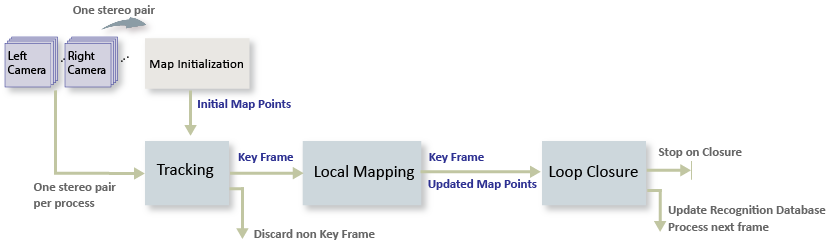

- **Map Initialization**: The pipeline starts by initializing the map of 3-D points from a pair of stereo images using the disparity map. The left image is stored as the first key frame. 

- **Tracking**: Once a map is initialized, for each new stereo pair, the pose of the camera is estimated by matching features in the left image to features in the last key frame. The estimated camera pose is refined by tracking the local map.

- **Local Mapping**: If the current left image is identified as a key frame, new 3-D map points are computed from the disparity of the stereo pair.  At this stage, bundle adjustment is used to minimize reprojection errors by adjusting the camera pose and 3-D points.  

- **Loop Closure**: Loops are detected for each key frame by comparing it against all previous key frames using the bag-of-features approach. Once a loop closure is detected, the pose graph is optimized to refine the camera poses of all the key frames.

## **Download and Explore the Input Stereo Image Sequence**

The data used in this example are from the [UTIAS Long-Term Localization and Mapping Dataset](http://asrl.utias.utoronto.ca/datasets/2020-vtr-dataset/) provided by University of Toronto Institute for Aerospace Studies. You can download the data to a temporary directory using a web browser or by running the following code:

tempFolder   = fullfile('.');
dataFolder   = ['2020-vtr-dataset/UTIAS-In-The-Dark/'];
zipFileName  = [dataFolder, 'run_000005.zip'];
folderExists = exist(dataFolder, 'dir');

% Create a folder in a temporary directory to save the downloaded file
if ~folderExists  
    ftpObj       = ftp('asrl3.utias.utoronto.ca');
    mkdir(dataFolder); 
    disp('Downloading run_000005.zip (818 MB). This download can take a few minutes.') 
    mget(ftpObj,'/2020-vtr-dataset/UTIAS-In-The-Dark/run_000005.zip', tempFolder);

    % Extract contents of the downloaded file
    disp('Extracting run_000005.zip (818 MB) ...') 
    unzip(zipFileName, dataFolder); 
end

Error using matlab.io.internal.ftp.FTPHelper/connect (line 22)
Could not open a connection to "asrl3.utias.utoronto.ca", port "21".

Error in matlab.io.internal.ftp.FTPHelper (line 37)
            connect(obj);

Error in 

Use two [`imageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) objects to store the stereo images.

imgFolderLeft  = [dataFolder,'images/left/'];
imgFolderRight = [dataFolder,'images/right/'];
imdsLeft       = imageDatastore(imgFolderLeft);
imdsRight      = imageDatastore(imgFolderRight);

% Inspect the first pair of images
currFrameIdx   = 1;
currILeft      = readimage(imdsLeft, currFrameIdx);
currIRight     = readimage(imdsRight, currFrameIdx);
imshowpair(currILeft, currIRight, 'montage');

## **Map Initialization**

The ORB-SLAM pipeline starts by initializing the map that holds 3-D world points. This step is crucial and has a significant impact on the accuracy of final SLAM result. Initial ORB feature point correspondences are found using [`matchFeatures`](https://www.mathworks.com/help/vision/ref/matchfeatures.html) between two images of a stereo pair. The matched pairs should satisfy the following constraints:

- The horizontal shift between the two corresponding feature points in the rectified stereo pair image is less than the maximum disparity. You can determine the approximate maximum disparity value from the stereo anaglyph of the stereo pair image. For more information, see [Choosing Range of Disparity. ](https://www.mathworks.com/help/vision/ref/disparitysgm.html#mw_78abe5d9-33f5-4849-bf64-aef262c144fe_head)

- The vertical shift between the two corresponding feature points in the rectified stereo pair image is less than a threshold.

- The scales of the matched features are nearly identical.

The 3-D world locations corresponding to the matched feature points are determined as follows:

- Use [`disparitySGM`](https://www.mathworks.com/help/vision/ref/disparitysgm.html) to compute the disparity map for each pair of stereo images by using semi-global matching (SGM) method.  

- Use [`reconstructScene`](https://www.mathworks.com/help/vision/ref/reconstructscene.html) to compute the 3-D world point coordinates from the disparity map. 

- Find the locations in the disparity map that correspond to the feature points and their 3-D world locations.

% Set random seed for reproducibility
rng(0);

% Load the initial camera pose. The initial camera pose is derived based 
% on the transformation between the camera and the vehicle:
% http://asrl.utias.utoronto.ca/datasets/2020-vtr-dataset/text_files/transform_camera_vehicle.tx 
initialPoseData = load('initialPose.mat');
initialPose     = initialPoseData.initialPose;

% Create a stereoParameters object to store the stereo camera parameters.
% The intrinsics for the dataset can be found at the following page:
% http://asrl.utias.utoronto.ca/datasets/2020-vtr-dataset/text_files/camera_parameters.txt
focalLength     = [387.777 387.777];     % specified in pixels
principalPoint  = [257.446 197.718];     % specified in pixels [x, y]
baseline        = 0.239965;              % specified in meters
intrinsicMatrix = [focalLength(1), 0, 0; ...
    0, focalLength(2), 0; ...
    principalPoint(1), principalPoint(2), 1];
imageSize       = size(currILeft,[1,2]); % in pixels [mrows, ncols]
cameraParam     = cameraParameters('IntrinsicMatrix', intrinsicMatrix, 'ImageSize', imageSize);
intrinsics      = cameraParam.Intrinsics;
stereoParams    = stereoParameters(cameraParam, cameraParam, eye(3), [-baseline, 0 0]);

% In this example, the images are already undistorted. In a general
% workflow, uncomment the following code to undistort the images.
% currILeft  = undistortImage(currILeft, intrinsics);
% currIRight = undistortImage(currIRight, intrinsics);

% Rectify the stereo images
[currILeft, currIRight] = rectifyStereoImages(currILeft, currIRight, stereoParams, 'OutputView','full');

% Detect and extract ORB features from the rectified stereo images
scaleFactor = 1.2;
numLevels   = 8;
[currFeaturesLeft,  currPointsLeft]   = helperDetectAndExtractFeatures(currILeft, scaleFactor, numLevels); 
[currFeaturesRight, currPointsRight]  = helperDetectAndExtractFeatures(currIRight, scaleFactor, numLevels);

% Match feature points between the stereo images and get the 3-D world positions 
maxDisparity = 48;  % specified in pixels
[xyzPoints, matchedPairs] = helperReconstructFromStereo(currILeft, currIRight, ...
    currFeaturesLeft, currFeaturesRight, currPointsLeft, currPointsRight, stereoParams, initialPose, maxDisparity);

## Data Management and Visualization

After the map is initialized using the first stereo pair, you can use [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78)`,` [`worldpointset`](docid:vision_ref#mw_3d5c7b4a-5b50-436d-a8b0-f20fc3d7a466) and `helperViewDirectionAndDepth `to store the first key frames and the corresponding map points:

% Create an empty imageviewset object to store key frames
vSetKeyFrames = imageviewset;

% Create an empty worldpointset object to store 3-D map points
mapPointSet   = worldpointset;

% Create a helperViewDirectionAndDepth object to store view direction and depth 
directionAndDepth = helperViewDirectionAndDepth(size(xyzPoints, 1));

% Add the first key frame
currKeyFrameId = 1;
vSetKeyFrames = addView(vSetKeyFrames, currKeyFrameId, initialPose, 'Points', currPointsLeft,...
    'Features', currFeaturesLeft.Features);

% Add 3-D map points
[mapPointSet, stereoMapPointsIdx] = addWorldPoints(mapPointSet, xyzPoints);

% Add observations of the map points
mapPointSet = addCorrespondences(mapPointSet, currKeyFrameId, stereoMapPointsIdx, matchedPairs(:, 1));

% Visualize matched features in the first key frame
featurePlot = helperVisualizeMatchedFeaturesStereo(currILeft, currIRight, currPointsLeft, ...
    currPointsRight, matchedPairs);

% Visualize initial map points and camera trajectory
mapPlot     = helperVisualizeMotionAndStructureStereo(vSetKeyFrames, mapPointSet);

% Show legend
showLegend(mapPlot);

## Tracking

The tracking process is performed using every pair and determines when to insert a new key frame. 

% ViewId of the last key frame
lastKeyFrameId    = currKeyFrameId;

% ViewId of the reference key frame that has the most co-visible 
% map points with the current key frame
refKeyFrameId     = currKeyFrameId;

% Index of the last key frame in the input image sequence
lastKeyFrameIdx   = currFrameIdx; 

% Indices of all the key frames in the input image sequence
addedFramesIdx    = lastKeyFrameIdx;

currFrameIdx      = 2;
isLoopClosed      = false;

Each frame is processed as follows:

- ORB features are extracted for each new stereo pair of images and then matched (using [`matchFeatures`](docid:vision_ref#bsvbhh1-1)), with features in the last key frame that have known corresponding 3-D map points. 

- Estimate the camera pose with the Perspective-n-Point algorithm using [`estimateWorldCameraPose`](docid:vision_ref#bvcns9r-1).

- Given the camera pose, project the map points observed by the last key frame into the current frame and search for feature correspondences using  [`matchFeaturesInRadius`](docid:vision_ref#mw_098d719d-da7d-45dd-81aa-ddab5fdfc9a4)`. `

- With 3-D to 2-D correspondences in the current frame, refine the camera pose by performing a motion-only bundle adjustment using [`bundleAdjustmentMotion`](docid:vision_ref#mw_11887bed-7a1c-44d8-929a-e5401685ddcf). 

- Project the local map points into the current frame to search for more feature correspondences using [`matchFeaturesInRadius`](docid:vision_ref#mw_098d719d-da7d-45dd-81aa-ddab5fdfc9a4) and refine the camera pose again using [`bundleAdjustmentMotion`](docid:vision_ref#mw_11887bed-7a1c-44d8-929a-e5401685ddcf). 

- The last step of tracking is to decide if the current frame should be a new key frame. A frame is a key frame if both of the following conditions are satisfied:

- At least 5 frames have passed since the last key frame or the current frame tracks fewer than 100 map points.

- The map points tracked by the current frame are fewer than 90% of points tracked by the reference key frame.

            If the current frame is to become a key frame, continue to the **Local Mapping **process. Otherwise, start **Tracking** for the next frame.

% Main loop
while currFrameIdx < numel(imdsLeft.Files)

    currILeft  = readimage(imdsLeft, currFrameIdx);
    currIRight = readimage(imdsRight, currFrameIdx);
    [currILeft, currIRight] = rectifyStereoImages(currILeft, currIRight, stereoParams, 'OutputView','full');

    [currFeaturesLeft, currPointsLeft]    = helperDetectAndExtractFeatures(currILeft, scaleFactor, numLevels);
    [currFeaturesRight, currPointsRight]  = helperDetectAndExtractFeatures(currIRight, scaleFactor, numLevels);

    % Track the last key frame
    % trackedMapPointsIdx:  Indices of the map points observed in the current left frame 
    % trackedFeatureIdx:    Indices of the corresponding feature points in the current left frame
    [currPose, trackedMapPointsIdx, trackedFeatureIdx] = helperTrackLastKeyFrame(mapPointSet, ...
        vSetKeyFrames.Views, currFeaturesLeft, currPointsLeft, lastKeyFrameId, intrinsics, scaleFactor);
    
    if isempty(currPose) || numel(trackedMapPointsIdx) < 30
        currFrameIdx = currFrameIdx + 1;
        continue
    end
    
    % Track the local map
    % refKeyFrameId:      ViewId of the reference key frame that has the most 
    %                     co-visible map points with the current frame
    % localKeyFrameIds:   ViewId of the connected key frames of the current frame
    if currKeyFrameId == 1
        refKeyFrameId    = 1;
        localKeyFrameIds = 1;
    else
        [refKeyFrameId, localKeyFrameIds, currPose, trackedMapPointsIdx, trackedFeatureIdx] = ...
            helperTrackLocalMap(mapPointSet, directionAndDepth, vSetKeyFrames, trackedMapPointsIdx, ...
            trackedFeatureIdx, currPose, currFeaturesLeft, currPointsLeft, intrinsics, scaleFactor, numLevels);
    end
    
    % Match feature points between the stereo images and get the 3-D world positions
    [xyzPoints, matchedPairs] = helperReconstructFromStereo(currILeft, currIRight, currFeaturesLeft, ...
        currFeaturesRight, currPointsLeft, currPointsRight, stereoParams, currPose, maxDisparity);
    
    [untrackedFeatureIdx, ia] = setdiff(matchedPairs(:, 1), trackedFeatureIdx);
    xyzPoints = xyzPoints(ia, :);
    
    % Check if the current frame is a key frame
    isKeyFrame = helperIsKeyFrame(mapPointSet, refKeyFrameId, lastKeyFrameIdx, ...
        currFrameIdx, trackedMapPointsIdx);

    % Visualize matched features in the stereo image
    updatePlot(featurePlot, currILeft, currIRight, currPointsLeft, currPointsRight, trackedFeatureIdx, matchedPairs);
    
    if ~isKeyFrame
        currFrameIdx = currFrameIdx + 1;
        continue
    end
    
    % Update current key frame ID
    currKeyFrameId  = currKeyFrameId + 1;

## Local Mapping

Local mapping is performed for every key frame. When a new key frame is determined, add it to the key frames and update the attributes of the map points observed by the new key frame. To ensure that `mapPointSet` contains as few outliers as possible, a valid map point must be observed in at least 3 key frames. 

New map points are created by triangulating ORB feature points in the current key frame and its connected key frames. For each unmatched feature point in the current key frame, search for a match with other unmatched points in the connected key frames using [`matchFeatures`](docid:vision_ref#bsvbhh1-1). The local bundle adjustment refines the pose of the current key frame, the poses of connected key frames, and all the map points observed in these key frames.


    % Add the new key frame    
    [mapPointSet, vSetKeyFrames] = helperAddNewKeyFrame(mapPointSet, vSetKeyFrames, ...
        currPose, currFeaturesLeft, currPointsLeft, trackedMapPointsIdx, trackedFeatureIdx, localKeyFrameIds);
        
    % Remove outlier map points that are observed in fewer than 3 key frames
    if currKeyFrameId == 2
        triangulatedMapPointsIdx = [];
    end
    
    [mapPointSet, directionAndDepth, trackedMapPointsIdx] = ...
        helperCullRecentMapPoints(mapPointSet, directionAndDepth, trackedMapPointsIdx, triangulatedMapPointsIdx, ...
        stereoMapPointsIdx);
    
    % Add new map points computed from disparity 
    [mapPointSet, stereoMapPointsIdx] = addWorldPoints(mapPointSet, xyzPoints);
    mapPointSet = addCorrespondences(mapPointSet, currKeyFrameId, stereoMapPointsIdx, ...
        untrackedFeatureIdx);
    
    % Create new map points by triangulation
    minNumMatches = 10;
    minParallax   = 0.35;
    [mapPointSet, vSetKeyFrames, triangulatedMapPointsIdx, stereoMapPointsIdx] = helperCreateNewMapPointsStereo( ...
        mapPointSet, vSetKeyFrames, currKeyFrameId, intrinsics, scaleFactor, minNumMatches, minParallax, ...
        untrackedFeatureIdx, stereoMapPointsIdx);
    
    % Update view direction and depth
    directionAndDepth = update(directionAndDepth, mapPointSet, vSetKeyFrames.Views, ...
        [trackedMapPointsIdx; triangulatedMapPointsIdx; stereoMapPointsIdx], true);
    
    % Local bundle adjustment
    [mapPointSet, directionAndDepth, vSetKeyFrames, triangulatedMapPointsIdx, stereoMapPointsIdx] = ...
        helperLocalBundleAdjustmentStereo(mapPointSet, directionAndDepth, vSetKeyFrames, ...
        currKeyFrameId, intrinsics, triangulatedMapPointsIdx, stereoMapPointsIdx); 
    
    % Visualize 3-D world points and camera trajectory
    updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

## Loop Closure

The loop closure step takes the current key frame processed by the local mapping process and tries to detect and close the loop. Loop detection is performed using the bags-of-words approach. A visual vocabulary represented as a [`bagOfFeatures`](docid:vision_ref#bufbdd6) object is created offline with the SURF descriptors extracted from a large set of images in the dataset by calling:

`bag = bagOfFeatures(imds,'CustomExtractor', @helperSURFFeatureExtractorFunction);`

where `imds` is an [`imageDatastore`](docid:matlab_ref#butueui-1) object storing the training images and [`helperSURFFeatureExtractorFunction`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperExtractorFunction.m')) is the SURF feature extractor function. See [Image Retrieval with Bag of Visual Words](docid:vision_ug#bun8icv-1) for more information.

The loop closure process incrementally builds a database, represented as an [`invertedImageIndex`](docid:vision_ref#bumxjai-1) object, that stores the visual word-to-image mapping based on the bag of SURF features. Loop candidates are identified by querying images in the database that are visually similar to the current key frame using [`evaluateImageRetrieval`](docid:vision_ref#bumxi3p-1). A candidate key frame is valid if it is not connected to the last key frame and three of its neighbor key frames are loop candidates. 

When a valid loop closure candidate is found, compute the relative pose between the loop closure candidate frame and the current key frame using [`estimateGeometricTransform3D`](docid:vision_ref#mw_8da50fc3-fafc-4dac-851c-d2826a374654). Then add the loop connection with the relative pose and update `mapPointSet `and `vSetKeyFrames`.

     % Initialize the loop closure database
    if currKeyFrameId == 2
        % Load the bag of features data created offline
        bofData         = load('bagOfFeaturesUTIAS.mat');
        
        % Initialize the place recognition database
        loopCandidates  = [1; 2];
        loopDatabase    = indexImages(subset(imdsLeft, loopCandidates), bofData.bof);
       
    % Check loop closure after some key frames have been created    
    elseif currKeyFrameId > 50
        
        % Minimum number of feature matches of loop edges
        loopEdgeNumMatches = 40;
        
        % Detect possible loop closure key frame candidates
        [isDetected, validLoopCandidates] = helperCheckLoopClosure(vSetKeyFrames, currKeyFrameId, ...
            loopDatabase, currILeft, loopCandidates, loopEdgeNumMatches);
        
        isTooCloseView = currKeyFrameId - max(validLoopCandidates) < 20;
        if isDetected && ~isTooCloseView
            % Add loop closure connections
            [isLoopClosed, mapPointSet, vSetKeyFrames] = helperAddLoopConnectionsStereo(...
                mapPointSet, vSetKeyFrames, validLoopCandidates, currKeyFrameId, ...
                currFeaturesLeft, currPointsLeft, loopEdgeNumMatches);
        end
    end
    
    % If no loop closure is detected, add the image into the database
    if ~isLoopClosed
        addImages(loopDatabase, subset(imdsLeft, currFrameIdx), 'Verbose', false);
        loopCandidates= [loopCandidates; currKeyFrameId];  
    end
    
    % Update IDs and indices
    lastKeyFrameId  = currKeyFrameId;
    lastKeyFrameIdx = currFrameIdx;
    addedFramesIdx  = [addedFramesIdx; currFrameIdx]; 
    currFrameIdx    = currFrameIdx + 1;
end % End of main loop

Finally, apply pose graph optimization over the essential graph in `vSetKeyFrames `to correct the drift. The essential graph is created internally by removing connections with fewer than `minNumMatches `matches in the covisibility graph. After pose graph optimization, update the 3-D locations of the map points using the optimized poses.

% Optimize the poses
minNumMatches = 10;
vSetKeyFramesOptim = optimizePoses(vSetKeyFrames, minNumMatches, 'Tolerance', 1e-16);

% Update map points after optimizing the poses
mapPointSet = helperUpdateGlobalMap(mapPointSet, directionAndDepth, vSetKeyFrames, vSetKeyFramesOptim);

updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

% Plot the optimized camera trajectory
optimizedPoses  = poses(vSetKeyFramesOptim);
plotOptimizedTrajectory(mapPlot, optimizedPoses)

% Update legend
showLegend(mapPlot);

## Compare with the Ground Truth

You can compare the optimized camera trajectory with the ground truth to evaluate the accuracy of the solution. The downloaded data contains a `gps.txt` file that stores the GPS location for each frame. You can convert the GPS location from geographic to local Cartesian coordinates using [`latlon2local`](docid:driving_ref#mw_80e7a72c-09f3-40cc-a4c7-2472f5c534d9) from Automated Driving Toolbox or [`geodetic2enu`](docid:map_ref#btms7xj-1) from Mapping Toolbox. In this example, you can simply load the converted GPS data from an M-file.

% Load GPS data
gpsData     = load('gpsLocation.mat');
gpsLocation = gpsData.gpsLocation;

% Transform GPS locations to the reference coordinate system
gTruth = helperTransformGPSLocations(gpsLocation, optimizedPoses);

% Plot the GPS locations
plotActualTrajectory(mapPlot, gTruth(addedFramesIdx, :));

% Show legend
showLegend(mapPlot);

## Supporting Functions

Short helper functions are listed below. Larger function are included in separate files.

`helperDetectAndExtractFeatures` detect and extract and ORB features from the image.

function [features, validPoints] = helperDetectAndExtractFeatures(Irgb, scaleFactor, numLevels)
 
numPoints = 800;

% Detect ORB features
Igray  = rgb2gray(Irgb);

points = detectORBFeatures(Igray, 'ScaleFactor', scaleFactor, 'NumLevels', numLevels);

% Select a subset of features, uniformly distributed throughout the image
points = selectUniform(points, numPoints, size(Igray, 1:2));

% Extract features
[features, validPoints] = extractFeatures(Igray, points);
end

`helperReconstructFromStereo `reconstruct scene from stereo image using the disparity map

function [xyzPoints, indexPairs] = helperReconstructFromStereo(I1, I2, ...
    features1, features2, points1, points2, stereoParams, currPose, maxDisparity)

indexPairs     = helperFindValidFeaturePairs(features1, features2, points1, points2, maxDisparity);

% Compute disparity for all pixels in the left image. In practice, it is more 
% common to compute disparity just for the matched feature points.
disparityMap   = disparitySGM(rgb2gray(I1), rgb2gray(I2), 'DisparityRange', [0, maxDisparity]);
xyzPointsAll   = reconstructScene(disparityMap, stereoParams);

% Find the corresponding world point of the matched feature points 
locations      = floor(points1.Location(indexPairs(:, 1), [2 1]));
xyzPoints      = [];
isPointFound   = false(size(points1));

for i = 1:size(locations, 1)
    point3d = squeeze(xyzPointsAll(locations(i,1), locations(i, 2), :))';
    isPointValid   = all(~isnan(point3d)) && all(isfinite(point3d)) &&  point3d(3) > 0;
    isDepthInRange = point3d(3) < 200*norm(stereoParams.TranslationOfCamera2);
    if isPointValid  && isDepthInRange
        xyzPoints       = [xyzPoints; point3d]; %#ok<*AGROW> 
        isPointFound(i) = true;
    end
end
indexPairs = indexPairs(isPointFound, :);
xyzPoints  = xyzPoints * currPose.Rotation + currPose.Translation;
end

`helperFindValidFeaturePairs `match features between a pair of stereo images

function indexPairs = helperFindValidFeaturePairs(features1, features2, points1, points2, maxDisparity)
indexPairs  = matchFeatures(features1, features2,...
    'Unique', true, 'MaxRatio', 1, 'MatchThreshold', 40);

matchedPoints1 = points1.Location(indexPairs(:,1), :);
matchedPoints2 = points2.Location(indexPairs(:,2), :);
scales1        = points1.Scale(indexPairs(:,1), :);
scales2        = points2.Scale(indexPairs(:,2), :);

dist2EpipolarLine = abs(matchedPoints2(:, 2) - matchedPoints1(:, 2));
shiftDist = matchedPoints1(:, 1) - matchedPoints2(:, 1);

isCloseToEpipolarline = dist2EpipolarLine < 2*scales2;
isDisparityValid      = shiftDist > 0 & shiftDist < maxDisparity;
isScaleIdentical      = scales1 == scales2;
indexPairs = indexPairs(isCloseToEpipolarline & isDisparityValid & isScaleIdentical, :);
end


`helperIsKeyFrame` check if a frame is a key frame.

function isKeyFrame = helperIsKeyFrame(mapPoints, ...
    refKeyFrameId, lastKeyFrameIndex, currFrameIndex, mapPointsIndices)

numPointsRefKeyFrame = numel(findWorldPointsInView(mapPoints, refKeyFrameId));

% More than 10 frames have passed from last key frame insertion
tooManyNonKeyFrames = currFrameIndex >= lastKeyFrameIndex + 10;

% Track less than 100 map points
tooFewMapPoints     = numel(mapPointsIndices) < max(100, 0.25 * numPointsRefKeyFrame);

% Tracked map points are fewer than 90% of points tracked by
% the reference key frame
tooFewTrackedPoints = numel(mapPointsIndices) < 0.9 * numPointsRefKeyFrame;

isKeyFrame = (tooManyNonKeyFrames && tooFewTrackedPoints) || tooFewMapPoints;
end

`helperCullRecentMapPoints` cull recently added map points.

function [mapPointSet, directionAndDepth, mapPointsIdx] = ...
    helperCullRecentMapPoints(mapPointSet, directionAndDepth, mapPointsIdx, newPointIdx, stereoMapPointsIndices)

outlierIdx = setdiff([newPointIdx; stereoMapPointsIndices], mapPointsIdx);

if ~isempty(outlierIdx)
    mapPointSet   = removeWorldPoints(mapPointSet, outlierIdx);
    directionAndDepth = remove(directionAndDepth, outlierIdx);
    mapPointsIdx  = mapPointsIdx - arrayfun(@(x) nnz(x>outlierIdx), mapPointsIdx);
end

end

`helperUpdateGlobalMap` update 3-D locations of map points after pose graph optimization

function [mapPointSet, directionAndDepth] = helperUpdateGlobalMap(...
    mapPointSet, directionAndDepth, vSetKeyFrames, vSetKeyFramesOptim)

posesOld     = vSetKeyFrames.Views.AbsolutePose;
posesNew     = vSetKeyFramesOptim.Views.AbsolutePose;
positionsOld = mapPointSet.WorldPoints;
positionsNew = positionsOld;
indices = 1:mapPointSet.Count;

% Update world location of each map point based on the new absolute pose of 
% the corresponding major view
for i = 1: mapPointSet.Count
    majorViewIds = directionAndDepth.MajorViewId(i);
    tform = posesOld(majorViewIds).T \ posesNew(majorViewIds).T ;
    positionsNew(i, :) = positionsOld(i, :) * tform(1:3,1:3) + tform(4, 1:3);
end
mapPointSet = updateWorldPoints(mapPointSet, indices, positionsNew);
end

`helperTransformGPSLocations` transform the GPS locations to the reference coordinate system 

function gTruth = helperTransformGPSLocations(gpsLocations, optimizedPoses)

initialYawGPS  = atan( (gpsLocations(100, 2) - gpsLocations(1, 2)) / ...
    (gpsLocations(100, 1) - gpsLocations(1, 1)));
initialYawSLAM = atan((optimizedPoses.AbsolutePose(50).Translation(2) - ...
    optimizedPoses.AbsolutePose(1).Translation(2)) / ...
    (optimizedPoses.AbsolutePose(59).Translation(1) - ...
    optimizedPoses.AbsolutePose(1).Translation(1)));

relYaw = initialYawGPS - initialYawSLAM;
relTranslation = optimizedPoses.AbsolutePose(1).Translation;

initialTform = rotationVectorToMatrix([0 0 relYaw]);
for i = 1:size(gpsLocations, 1)
    gTruth(i, :) =  initialTform * gpsLocations(i, :)' + relTranslation';
end
end

## References

[1] Mur-Artal, Raul, and Juan D. Tardós. "ORB-SLAM2: An open-source SLAM system for monocular, stereo, and RGB-D cameras." *IEEE Transactions on Robotics* 33, no. 5 (2017): 1255-1262.

*Copyright 2020 The MathWorks, Inc.*